# Create and Customize 2-D Histograms

Bivariate or 2-D histograms are a type of bar plot for numeric data that group data into 2-D bins. 

## Read Ride Data

We will use "`rideData.mat" `to demonstrate how to create and customize bivariate histograms. The MAT-file contains data from Boston"s bike sharing program about the age of cyclists and the distance they cycled. 

load("rideData.mat")

## Basic Bivariate Histogram

View the relationship between the age and the distance for more than 200 thousand cyclists.

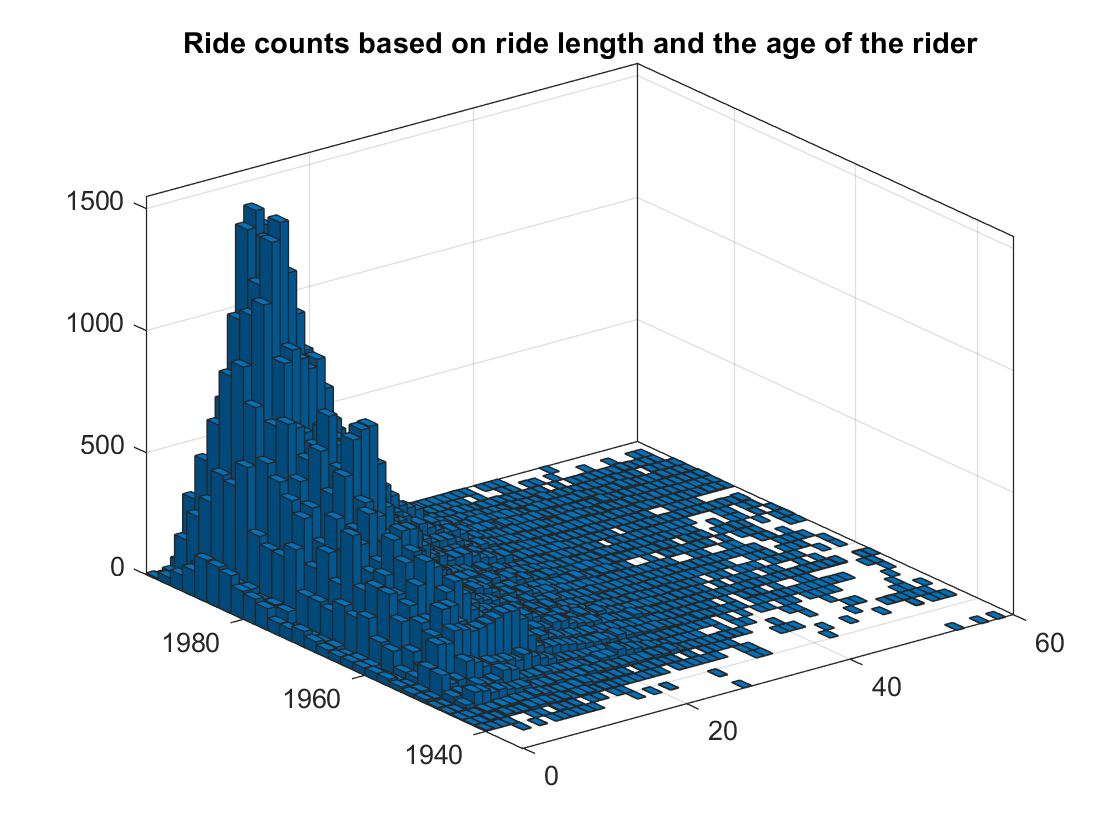

histogram2(rideData.Duration, rideData.birth_date)
title("Ride counts based on ride length and the age of the rider")

## Customization

### Specify Bin Width and Change View Angle

Observe how the distribution changes when the bin width is specified using the *BinWidth* Name, Value pair argument to `histogram2`. When *BinWidth* is not specified, an automatic binning algorithm returns bins with a uniform width. Change the view perspective to better visualize the data.

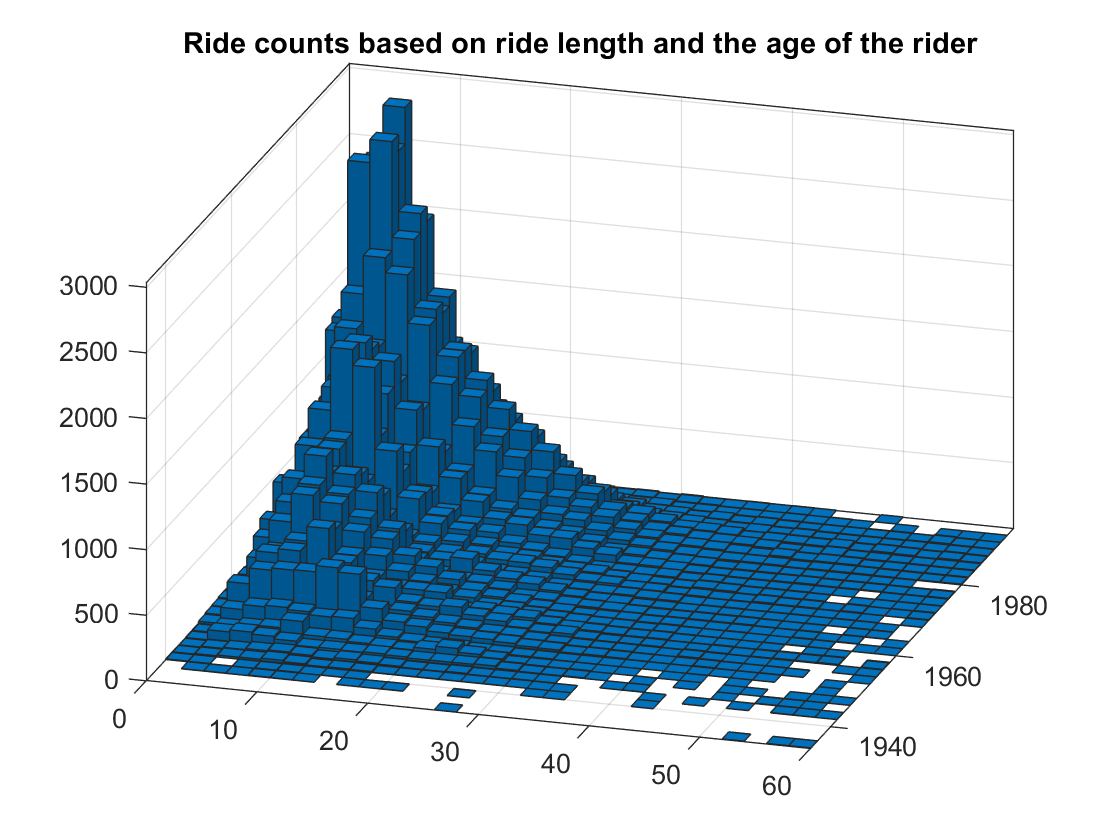

BinWidth = 2;
h = histogram2(rideData.Duration, rideData.birth_date,...
    "BinWidth",BinWidth);                                           % Specify the width of each bin
title("Ride counts based on ride length and the age of the rider")
view(17,30)                                                         % Specify the viewing perspective

### Use a Tiled Display and Customize a Colorbar

You could also view the 2-D histogram as a rectangular array of tiles by changing the *DisplayStyle* property. The bins are automatically colored if the "tile" option is specified. Use the *ShowEmptyBins* Name, Value pair argument to change whether empty bins are displayed. Add a colorbar with a label.

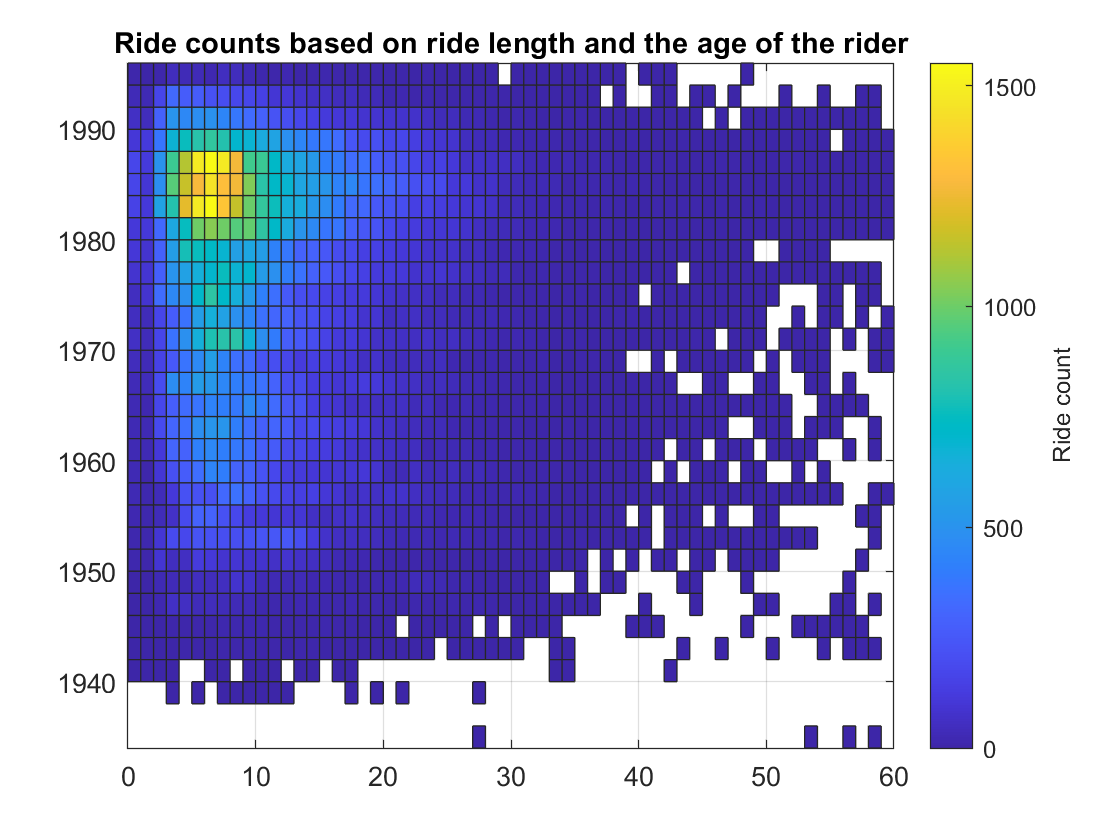

ShowEmptyBins = false;

figure
h1 = histogram2(rideData.Duration, rideData.birth_date,... 
   "DisplayStyle","tile",...           % Use "tile" for an array display
   "ShowEmptyBins",ShowEmptyBins);     % Specify whether empty bins should show

c = colorbar;                          % Use colorbar to display a legend
ylabel(c,"Ride count");                % Add a label to the colorbar

title("Ride counts based on ride length and the age of the rider")

### Change Bar Colors

To make taller bars stand out, the bar colors can be varied with height using the *FaceColor* property. Specify this property as "flat" to color the bars using the default colormap. Add axes labels for a complete plot.

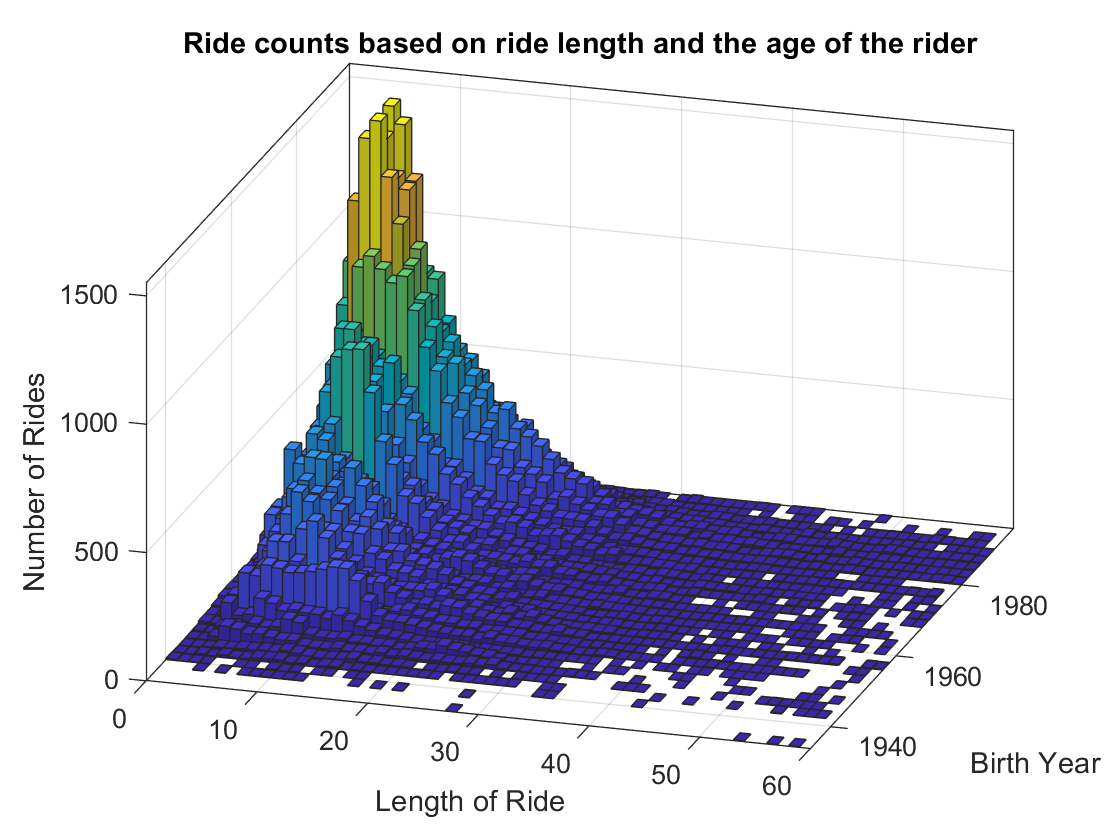

faceColorType = "flat";
h2 = histogram2(rideData.Duration, rideData.birth_date,...
   "FaceColor",faceColorType);                                          % Specify the bar color scheme

title("Ride counts based on ride length and the age of the rider")
xlabel("Length of Ride")
ylabel("Birth Year")
zlabel("Number of Rides")
view(17,30)

### Changing Chart Colormap

There are several default colormaps specified in MATLAB, some are shown in the drop down menu.

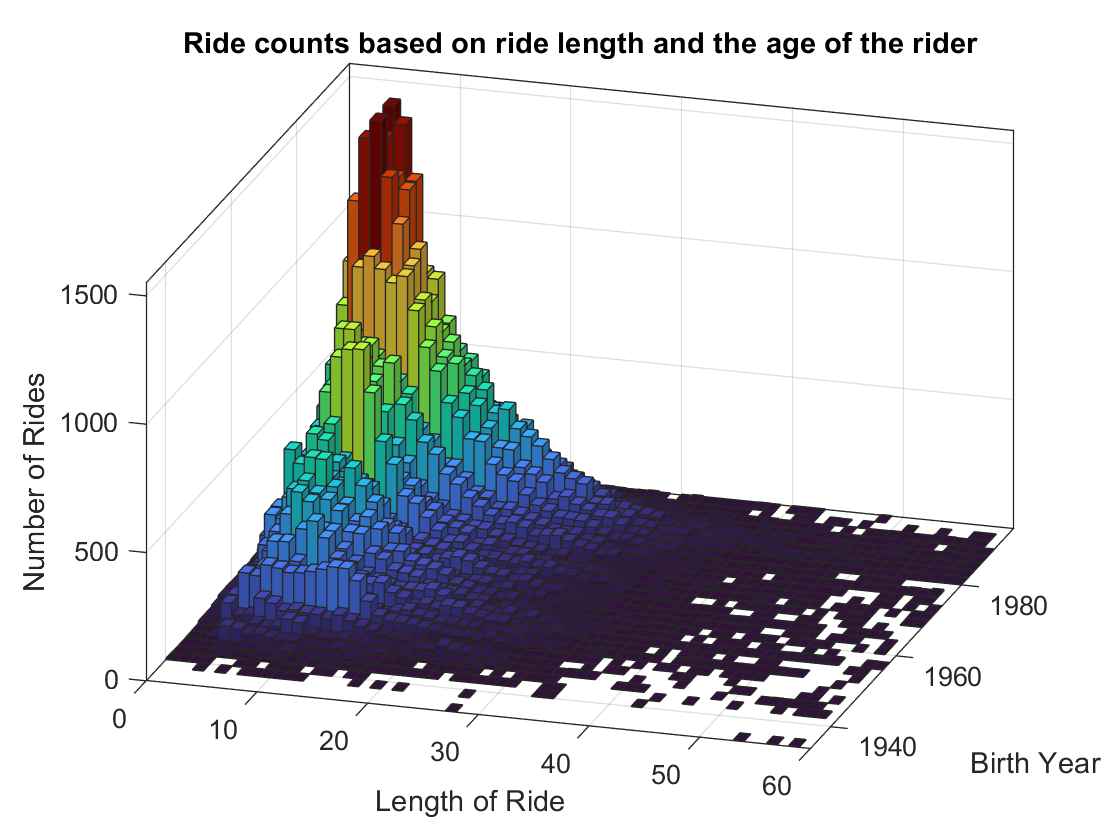

colormap("turbo"); % Specify colormap

## **Additional Information**

### **Get All Histogram2 Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Histogram2 object, uncomment the following code. View or modify these properties using dot notation.

% get(h)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[histogram2](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram2.html)

Copyright (c) 2021, The MathWorks, Inc.